Bewegung der MHT Einheit

Bereich der Kollisionsfrein bewegung

figure(1)
% motionfield
mf= [0 0 0   NaN NaN; ...
            10 -5 20  NaN NaN; ...
            20 -10 30  NaN NaN; ...
            30 -20 40 0 0; ...
            40 -30 30  -10 20; ...
            50 -40 35  -15 10; ...
            60 -30 40   -5 5 ; ...
            70 -60 60   -30 30; ...
            80 -70 50 0 0; ...
            90 -60 55 NaN NaN; ...
            100 -50 50 NaN NaN];
plot(mf(:,1),mf(:,[2,3, 4, 5]),'b*' )
hold on
~isnan(mf(:,4));
xx = 0:1:100;
x=mf(:,1)

x =      0
    10
    20
    30
    40
    50
    60
    70
    80
    90


for i=2:3
y =mf(:,i);
yy = spline(x,y,xx);
plot(xx,yy,'b' )
end
xx = 30:80;
for i=4:5
x=mf(~isnan(mf(:,4)),1);
y=mf(~isnan(mf(:,4)),i);
yy = spline(x,y,xx);
plot(xx,yy,'b' )
end 
grid on
hold on


Gnerate random Pos

n=0;
x=rand()*100;
y=rand()*200-100;
while ~inArea(mf, x,y)
    x=rand()*100;
    y=rand()*200-100;
    if n>100
        break 
    end
        n=n+1; 
  
end
    plot(x,y,'ro')
    xlabel('\theta 1')
    ylabel('\theta 2')
    title('Allowed Areas')
    
    
   

    

Find Path home

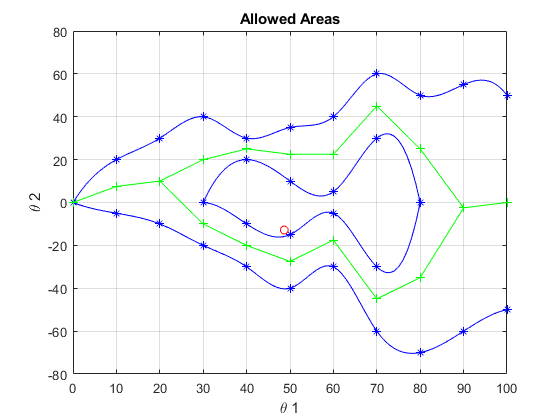

   p=zeros(size(mf,1),2);
    for i=1:size(mf,1)
       if isnan(mf(i,4)) 
         p(i,:)= [(mf(i,2)+mf(i,3))/2, (mf(i,2)+mf(i,3))/2];
        else
         p(i,:)= [(mf(i,2)+mf(i,4))/2 , (mf(i,3)+mf(i,5))/2];
        end
     end
     plot(mf(:,1),p,'g')
     plot(mf(:,1),p,'g+')
     
 
 
     hold off

    rd= 0.65;
    rd1= rd-0.01;
   
    ld = 0.2592;
    hd = ld*sqrt(3)/2;
    hm= ld/(2*sqrt(3));
    pd = asind(ld/(2*rd1)); 
    rd2= sqrt(rd1*rd1-(ld/2)*(ld/2));
    hr= rd2-hm

hr = 0.5519

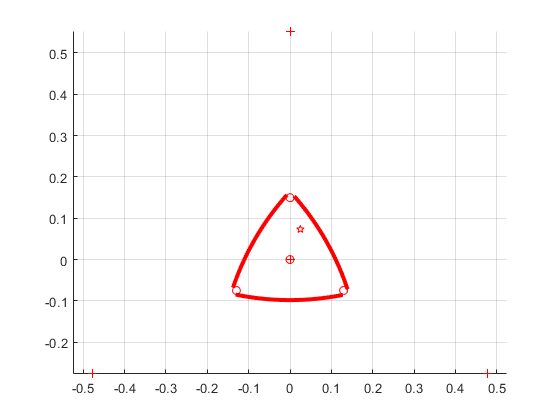

    pr= -pd:pd; 
    figure(4)
    hold on
    plot([0 -ld/2 0 ld/2],[0, -hm hd-hm -hm],'ro')
    plot([0 0 ,hr*cosd(-30),-hr*cosd(-30)],[0, hr, hr*sind(-30), hr*sind(-30)],'r+')
    plot(0+rd*cosd(pr-90),hr+rd*sind(pr-90),'r','LineWidth',3);

    plot(hr*cosd(-30)+rd*cosd(pr+150),hr*sind(-30)+rd*sind(pr+150),'r','LineWidth',3);
    plot(-hr*cosd(-30)+rd*cosd(pr+30),hr*sind(-30)+rd*sind(pr+30),'r','LineWidth',3);
    ox=0.025;
    oy= 0.1481-hm;
    
    plot([ox],[oy], 'rp')
   
    axis equal
    grid on
    hold off

Collision check

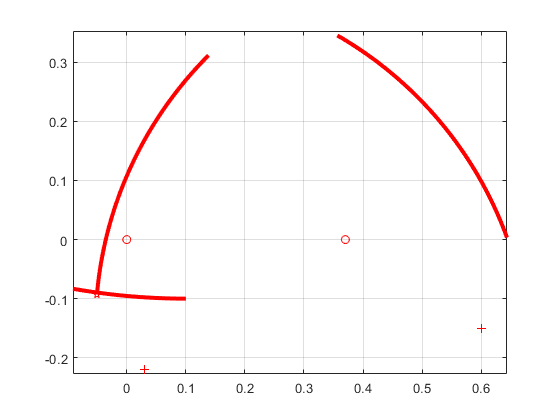

  
     
    figure(2)
    box.plot=3; % Plot etherything
    x1=0; y1=0;
    
    
    
    
    
    box.x1=0; box.y1=0;
    box.x2=0.37; box.y2=0;

    box.k1.m(1)=0.6;
    box.k1.m(2)=-0.15;
    box.k1.r=0.653;
    box.k1.p=(135:175);
    plot([x1 box.x2 ],[y1 box.y2], 'ro');
    hold on
    plot(box.k1.m(1)+box.k1.r*cosd(box.k1.p),box.k1.m(2)+box.k1.r*sind(box.k1.p),'r','LineWidth',3);
    box.P1= [box.k1.m(1)+box.k1.r*cosd(max(box.k1.p)),box.k1.m(2)+box.k1.r*sind(max(box.k1.p))];
    plot([box.P1(1) ],[box.P1(2)], 'rp')
    box.k2.p= [0 0];
    box.k3.p= [0 0];
    
    box.k2.m(1)=0.03;
    box.k2.m(2)=-0.22;
    box.k2.r=0.653;
    box.k2.p=20:60;
    plot(box.k2.m(1)+box.k2.r*cosd(box.k2.p),box.k2.m(2)+box.k2.r*sind(box.k2.p),'r','LineWidth',3)
    plot([box.k1.m(1) box.k2.m(1) ],[box.k1.m(2) box.k2.m(2)], 'r+')
    
    box.k3.m(1)=0.2;
    box.k3.m(2)=0.37;
    box.k3.r=0.653;
    box.k3.p=260:300;
%   plot(box.k3.m(1)+box.k3.r*cosd(box.k3.p),box.k3.m(2)+box.k3.r*sind(box.k3.p),'r')
%   plot([ box.m3 ],[ box.my3], 'r+');
   
    
    box.k4.m(1)=0.1;
    box.k4.m(2)=1.0;
    box.k4.r=1.1;
    box.k4.p=260:270;
    plot(box.k4.m(1)+box.k4.r*cosd(box.k4.p),box.k4.m(2)+box.k4.r*sind(box.k4.p),'r','LineWidth',3);
    
   
    plotBassBox( box)

    
    %    plot([ box.m4 ],[ box.my4], 'r+'); % Ceter of outer shape
    step=3;
    wb1= -120:step:15;
    wb2= -180:step:120;
      nx=length(wb1);
      ny=length(wb2);
     flt= ones(nx,ny);
    for w1=1:nx
         for w2=1:ny
           clf
           if box.plot>0
               plotBassBox(box);
           end
           xbox=plotBox(box,wb1(w1),wb2(w2));
           kol= checkCollision(xbox);
           flt(w1,w2)=kol;
         
           end
    end
     hold off
     
    figure(3)
    [X,Y]=meshgrid(wb2,wb1);
    surf(X,Y,flt);
    
 %     xbox= plotBox(box,-20,55);
 %      checkCollision(xbox)
 %     xbox= plotBox(box,-60,125);
 %       checkCollision(xbox)
      
 
    
   
  
    
    


 function plotBassBox(box)
    plot([box.x1 box.x2 ],[box.y1 box.y2], 'ro');
    hold on
     grid on
    axis equal

    plot(box.k1.m(1)+box.k1.r*cosd(box.k1.p),box.k1.m(2)+box.k1.r*sind(box.k1.p),'r','LineWidth',3);

    plot(box.k2.m(1)+box.k2.r*cosd(box.k2.p),box.k2.m(2)+box.k2.r*sind(box.k2.p),'r','LineWidth',3)
    plot([box.k1.m(1) box.k2.m(1) ],[box.k1.m(2) box.k2.m(2)], 'r+')

    plot(box.k4.m(1)+box.k4.r*cosd(box.k4.p),box.k4.m(2)+box.k4.r*sind(box.k4.p),'r','LineWidth',3);
    plot([box.P1(1) ],[box.P1(2)], 'rp')

  
    

 end
   

Plotten der MHT-Box und berechnen der gedrehten koordinaten

     function xbox =plotBox(box, phi1, phi2)
     
     xbox=box;
     xbox.kx1.r = box.k1.r-0.03;
     xbox.kx2.r = box.k2.r-0.03;
     xbox.kx3.r = box.k3.r-0.03;
     r4= 0.3;
     
     phi12=phi1+phi2;
   
     xbox.phi12=phi12; 
     
     [xm, ym] = rot(box.x2,box.y2,phi1);
  
    
      [x11, y11] = rot(box.k1.m(1)-box.x2,box.k1.m(2)-box.y2,phi2);
      [x12, y12] = rot(box.k2.m(1)-box.x2,box.k2.m(2)-box.y2,phi2);
      [x13, y13] = rot(box.k3.m(1)-box.x2,box.k3.m(2)-box.y2,phi2);
       
      [x1, y1] = rot(x11,y11,phi1);
      [x2, y2] = rot(x12,y12,phi1);
      [x3, y3] = rot(x13,y13,phi1);
       xbox.kx1=  xbox.k1;
       xbox.kx1=  xbox.k1;
       xbox.kx1=  xbox.k1;
       
      xbox.kx1.p = box.k1.p+phi12;
      xbox.kx2.p = box.k2.p+phi12;
      xbox.kx3.p = box.k3.p+phi12;
     
      xbox.kx1.m=[x1+xm,y1+ym];
      xbox.kx2.m=[x2+xm,y2+ym];
      xbox.kx3.m=[x3+xm,y3+ym];
      
      xbox.P2= [xbox.kx1.m(1)+xbox.kx1.r*cosd(min(xbox.kx1.p)),xbox.kx1.m(2)+xbox.kx1.r*sind(min(xbox.kx1.p))];
      xbox.P3= [xbox.kx1.m(1)+xbox.kx1.r*cosd(max(xbox.kx1.p)),xbox.kx1.m(2)+xbox.kx1.r*sind(max(xbox.kx1.p))];
      P=(xbox.P2+xbox.P3)/2;
      R=[-(xbox.P3(2)-xbox.P2(2)),(xbox.P3(1)-xbox.P2(1))]/norm(xbox.P3-xbox.P2);
      xbox.P4= [P(1) + r4*R(1),P(2)+r4*R(2)];
      

      if box.plot >1 
    
      plot(xbox.kx1.m(1)+xbox.kx1.r*cosd(xbox.kx1.p),xbox.kx1.m(2)+xbox.kx1.r*sind(xbox.kx1.p), 'b');
      plot(xbox.kx2.m(1)+xbox.kx2.r*cosd(xbox.kx2.p),xbox.kx2.m(2)+xbox.kx2.r*sind(xbox.kx2.p), 'b');
      plot(xbox.kx3.m(1)+xbox.kx3.r*cosd(xbox.kx3.p),xbox.kx3.m(2)+xbox.kx3.r*sind(xbox.kx3.p), 'b');
      plot([xbox.kx1.m(1),xbox.kx2.m(1),xbox.kx3.m(1)],[xbox.kx1.m(2),xbox.kx2.m(2),xbox.kx3.m(2)], 'b+')
    
     
      
    
      plot([P(1)],[P(2) ], 'gp');
      plot([xbox.P2(1) xbox.P3(1) xbox.P4(1) ],[xbox.P2(2) xbox.P3(2), xbox.P4(2)], 'bp');
      plot([ xm ],[ ym], 'bo');
      end
      
    end
    

Prüfen auf Kollision

   %************************************   
   
   function nk= checkCollision(box)
    nk=0;
    
    % prüfe ecke 
    l= norm(box.P1 - box.P2);
    col='y';
    if(l<0.01)
        col='m';
        nk=nk+1;
    end
    if box.plot > 2
     plot([box.P1(1)  box.P2(1)],[box.P1(2)  box.P2(2)],col);
    end
   
 
    nk = nk+ checkPointCircle(box.P1, box.kx1,false); % Eckpunkt Bassbox Front MHT
    nk = nk+ checkPointCircle(box.P1, box.kx2,false); % Eckpunkt Bassbox Rechts MHT
    nk = nk+ checkPointCircle(box.P1, box.kx3,false); % Eckpunkt Bassbox Rechts MHT    

    nk = nk+ checkPointCircle(box.P2, box.k1,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P2, box.k2,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P2, box.k4,false); % rechte Ecke MHT Buch Vorn Bassbox

    nk = nk+ checkPointCircle(box.P3, box.k1,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P3, box.k2,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P3, box.k4,false); % rechte Ecke MHT Buch Vorn Bassbox

    nk = nk+ checkPointCircle(box.P4, box.k1,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P4, box.k2,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P4, box.k4,false); % rechte Ecke MHT Buch Vorn Bassbox

   end
   
    %************************************************
    
    function nk = checkPointCircle(P, cir,flag)
    nk=0;
     % prüfe Ecke 1 Mht auf bogen 1
    l=norm(P - cir.m);
   
    % prüfe ob auch Winkel stimmt 
    dx = P - cir.m;
    a= atan2d(dx(2), dx(1));
    if a<0 
        a=a+360 ;
    end
    
    mi= min(cir.p);
    ma= max(cir.p);
  
    col='y';
    if (a>=mi && a<=ma) % Ecke ist auserhalb Kreisbogen
        if ((l > cir.r) && flag ) || ((l < cir.r) && ~flag )
        nk= nk+1;
        col='m';
        end
    end
    if a<mi || a>ma % Auserhalb des Winkelfensters
      col= 'g';
    end
    if box.plot > 2
     plot([P(1)  cir.m(1)],[P(2)  cir.m(2)],col);
    end
    end
    
    

Rotation um Winkel phi

%************************************   
function [x, y] = rot(xo,yo, phi)
  x = cosd(phi)*xo - sind(phi)*yo;
  y = sind(phi)*xo + cosd(phi)*yo;
end
    

Prüft ob punkt im Feld

function b = inArea(mf, x,y)
% find index
in = ceil( x/10);
b1 = ( y> mf(in,2) && y<(mf(in,3)));
b2=    (y< mf(in,4) || y>(mf(in,5)));
b= b1 && (isnan(mf(in,4)) || b2) ;  
end